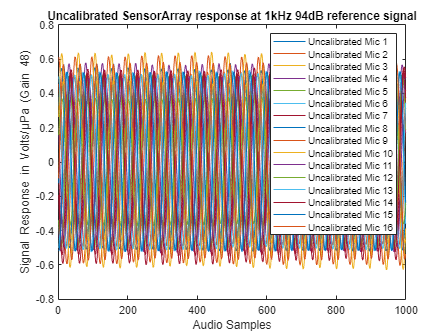

cDir = fileparts(matlab.desktop.editor.getActiveFilename);

NumberMics = 16;

CalbData = cell(1, 16);
Legend = cell(NumberMics,1);
for m = 1:NumberMics
    CalbData{:,m} = load(cDir+"\Calibration\" +sprintf('CalibrationMeasurment_MIC_%d.mat', m)).CalibrationMeas;
    plot(1:1000, CalbData{:, m}.RawMicData)
    Legend{m} = sprintf("Uncalibrated Mic %d", CalbData{:, m}.ChannelNumber);
    hold on
end
hold off
legend(Legend);
title(sprintf("Uncalibrated SensorArray response at 1kHz %ddB reference signal", CalbData{:, 1}.SPL))
xlabel("Audio Samples")
ylabel("Signal Response in Volts/\muPa (Gain 48)")

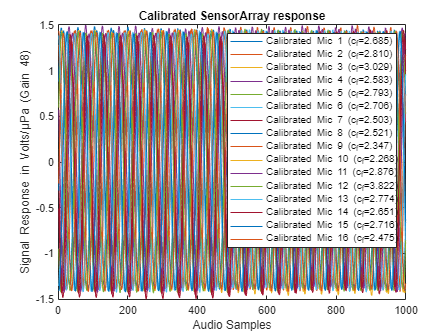


CalbData = cell(1, 16);
Legend = cell(NumberMics,1);
for m = 1:NumberMics
    CalbData{:,m} = load(cDir+"\Calibration\" +sprintf('CalibrationMeasurment_MIC_%d.mat', m)).CalibrationMeas;
    plot(1:1000, CalbData{:, m}.CalibratedMicData)
    Legend{m} = sprintf("Calibrated Mic %d (c_f=%0.3f)", CalbData{:, m}.ChannelNumber, CalbData{:, m}.calibrationFactor);
    hold on
end
hold off
legend(Legend);
title("Calibrated SensorArray response")
xlabel("Audio Samples")
ylabel("Signal Response in Volts/\muPa (Gain 48)")



LaTeX_Expr =    'c_f = \frac{10^\frac{SPL-k}{20}}{rms(x)}, \ \ \ k = 20log_{10}\left(\frac{1}{P_{ref}=20\mu Pa}\right)'

LaTeX_Expr = 'c_f = \frac{10^\frac{SPL-k}{20}}{rms(x)}, \ \ \ k = 20log_{10}\left(\frac{1}{P_{ref}=20\mu Pa}\right)'

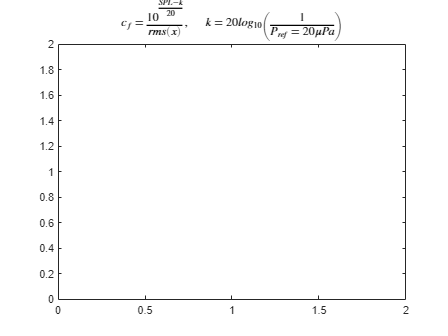

plot(1,1)
title(['$$' LaTeX_Expr '$$'], 'Interpreter','latex');

%%